clear
close all

# FUNÇÃO DE TRANSFERÊNCIA

Hs = tf(2 , [1 2 1]);
dt = 0.075;
Hz = c2d(Hs,dt);

# ESPAÇO DE ESTADOS

Hz_ss = ss(Hz)

Hz_ss =
 
  A = 
            x1       x2
   x1    1.855  -0.8607
   x2        1        0
 
  B = 
          u1
   x1  0.125
   x2      0
 
  C = 
            x1       x2
   y1  0.04281  0.04072
 
  D = 
       u1
   y1   0
 
Sample time: 0.075 seconds
Discrete-time state-space model.



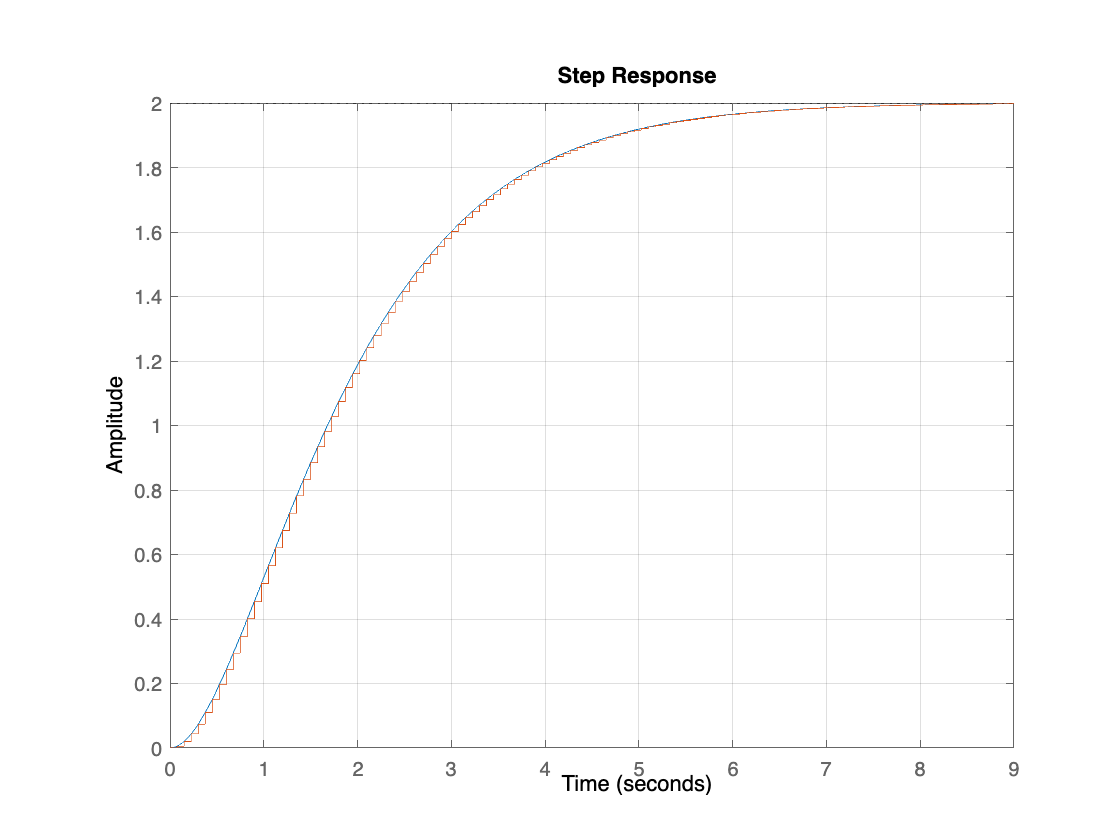

A = Hz_ss.A;
B = Hz_ss.B;
C = Hz_ss.C;
figure(1);
step(Hs,Hz_ss);
grid on;

# CONTROLADOR

Wn = 1;
ksi = 0.7;
z = exp(dt*roots([1,2*ksi*Wn,Wn^2]));
Pk = conv([1 ,-z(1)],[1, -z(2)]);
Pk_A = Pk(1) * A^2 + Pk(2) * A + Pk(3) * eye(2)

Pk_A =    -0.0337    0.0340
   -0.0395    0.0396


Wc = [Hz_ss.B Hz_ss.A*Hz_ss.B];
K = [0 1]/Wc * Pk_A

K =    -0.3160    0.3169


# ESTIMADOR

Pl_A = A^2;
Wo = [Hz_ss.C;Hz_ss.C*Hz_ss.A];
L = Pl_A/Wo * [0;1]

L =    26.8160
   17.3716


# GANHO Kc

Kc = 1/(C/(eye(2)-(A - (B * K))) * B)

Kc = 0.5111

# Malha Fechada

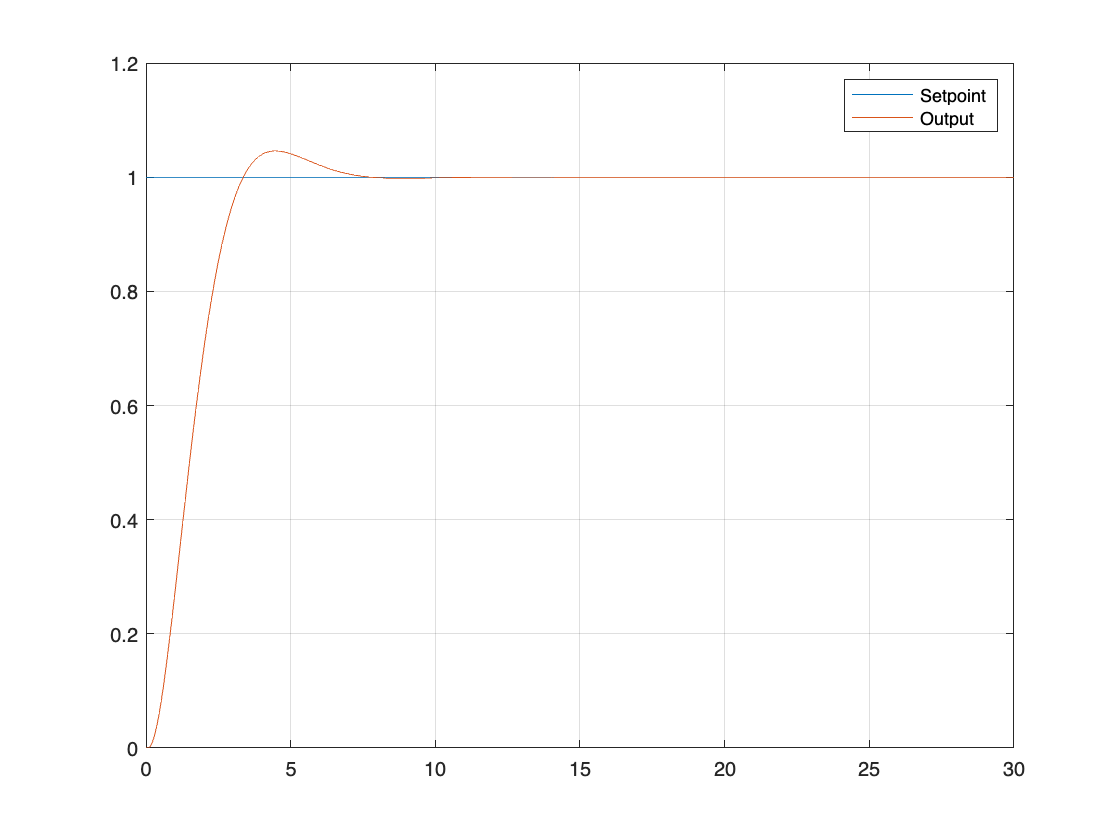

intervalo = 30;
n = intervalo / dt + 1;


wk = ones(1,n);
u = zeros(1,n);
x = zeros(2,n);
xee = zeros(2,n);
y = zeros(1,n);

t = 0:dt:intervalo;

for i = 1:n-1
    x(:,i+1) = A * x(:,i) + B * u(i);
    xee(:,i+1) = (A - L*C) * xee(:,i);    
    u(i+1) = -K * (x(:,i+1) - xee(:,i+1)) + Kc * wk(i+1);
    y(i+1) = C * x(:,i+1);
end

close(2)
figure(2)
plot(t,wk); hold on;
plot(t,y); hold on;
grid on;
legend("Setpoint", "Output");

figure(3)
plot(t,u); grid on;

u = zeros(1,n);
x = zeros(2,n);
xee = zeros(2,n);
y = zeros(1,n);

v = [zeros(1,15/dt + 1) ones(1,15/dt)];

v =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


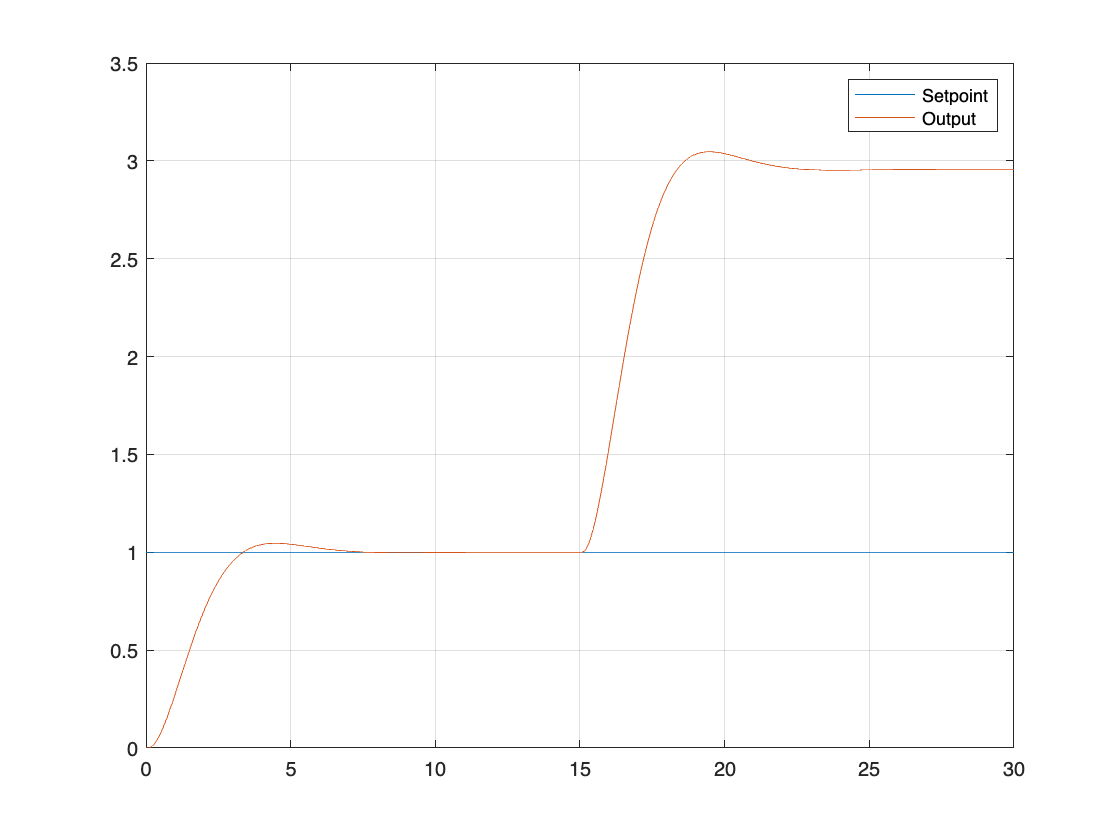


for i = 1:n-1
    x(:,i+1) = A * x(:,i) + B * (u(i) + v(i));
    xee(:,i+1) = (A - L*C) * xee(:,i);    
    u(i+1) = -K * (x(:,i+1) - xee(:,i+1)) + Kc * wk(i+1);
    y(i+1) = C * x(:,i+1);
end

% close(4)
figure(4)
plot(t,wk); hold on;
plot(t,y); hold on;
grid on;
legend("Setpoint", "Output");

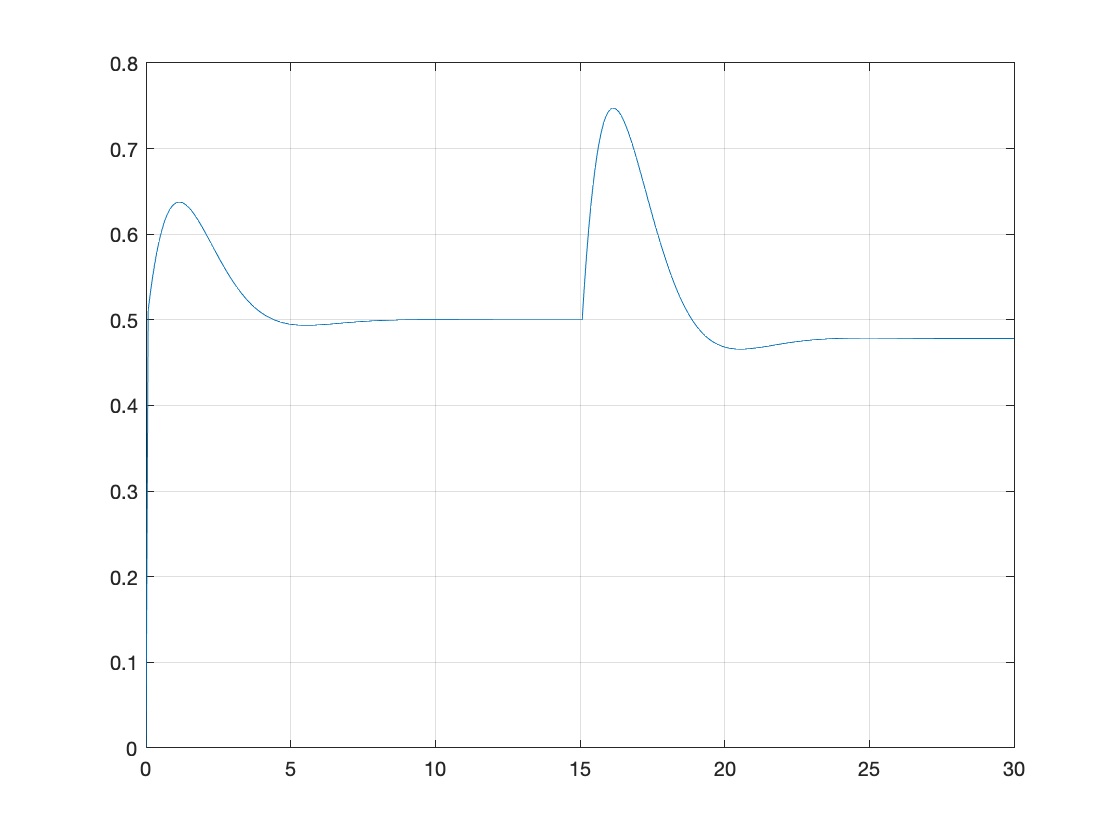


figure(5)
plot(t,u); grid on;